# Homework - 9

Collaborated with: Adtya Rathi

# Q1

A = [-0.2 2 2 0;
    0 -1 0 0;
    0 0 -2 0;
    0 0 0 -10];
B = [2 1 0;
    40 20 -20;
    60 30 -30;
    -2 -1 -3];
C = [1 0 0 -1;
    3 0 0 -3;
    0 1 1 0];
D = [0 0 0.9487;
    0 0 -0.3162;
    -0.4472 0.8944 0];
P = ss(A,B,C,D);
nmeas = 1;
ncont = 1;
[K,GAM] = hinfsynthesis(P,nmeas,ncont);

[Kinf,CL,GAM2] = hinfsyn(P,nmeas,ncont)

Kinf =
 
  A = 
             x1        x2        x3        x4
   x1   -0.1682    -2.511    -2.511  -0.01687
   x2       -62    -57.71     -56.1     23.14
   x3    -92.99    -84.47    -85.54     34.72
   x4    -9.426    0.2017    0.2951    -6.461
 
  B = 
           u1
   x1   4.515
   x2   44.46
   x3   66.08
   x4  -2.058
 
  C = 
           x1      x2      x3      x4
   y1   3.132  0.6172  0.5862  -1.174
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


CL =
 
  A = 
             x1        x2        x3        x4        x5        x6        x7        x8
   x1      -0.2         2         2         0         0         0         0         0
   x2         0        -1         0         0    -62.63    -12.34    -11.72     23.48
   x3         0         0        -2         0    -93.95    -18.52    -17.58     35.22
   x4         0         0         0       -10    -9.395    -1.852    -1.758     3.522
   x5         0     4.515     4.515         0   -0.1682    -2.511    -2.511  -

GAM2 = 32.0892

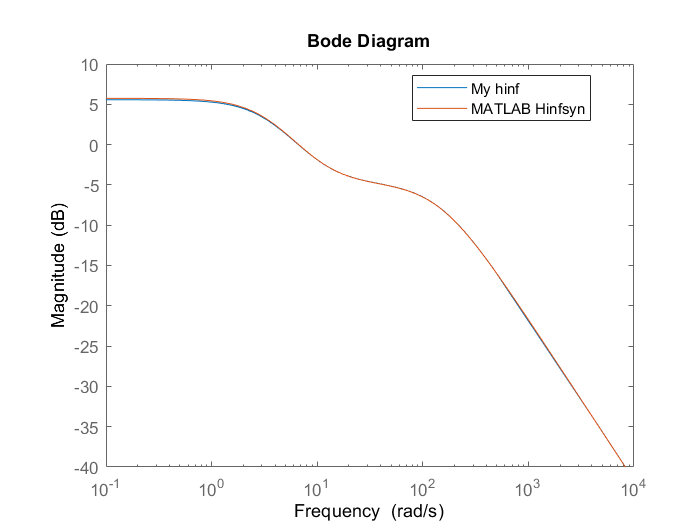

bodemag(K,Kinf)
legend("My hinf","MATLAB Hinfsyn","Location","best")

function [K,GAM] = hinfsynthesis(P,nmeas,ncont)
    A = P.A;
    B = P.B;
    C = P.C;
    D = P.D;
    B1 = B(:,1:end-ncont);
    B2 = B(:,end-ncont+1:end);
    C1 = C(1:end-nmeas,:);
    C2 = C(end-nmeas+1:end,:);
    D11 = D(1:end-nmeas,1:end-ncont);
    D12 = D(1:end-nmeas,end-ncont+1:end);
    D21 = D(end-nmeas+1:end,1:end-ncont);
    D22 = D(end-nmeas+1:end,end-ncont+1:end);
    
    gam_h = 100;
    gam_l = 0;
    gam_new = (gam_h+gam_l)/2;
    gam_try = gam_h;
    while abs(gam_new-gam_try) > 1e-5
        gam_try = gam_new;
        B_are_1 = B2*inv((D12')*D12)*B2' - (gam_try^(-2))*B1*(B1');
        C_are_1 = (C1')*C1;
        B_are_2 = C2'*inv(D21*(D21'))*C2 - (gam_try^(-2))*(C1')*C1;
        C_are_2 = B1*(B1');
        
        try
            X = are_sol(A,-B_are_1,C_are_1);
            Y = are_sol(A',-B_are_2,C_are_2);
            M = X*Y;
            rho = max(abs(eig(M)));
            if rho > gam_try^2
                gam_l = gam_try;
            else
                gam_h = gam_try;
            end
            GAM = gam_try;

        catch
            warning('Solution does not exist');
            gam_l = gam_try;
        end
        gam_new = 1/2*(gam_h+gam_l);
    end 
    m = length(M);
    Z = Y*inv(eye(m) - GAM^-2*X*Y);
    L_inf = Z*C2.'*inv(D21*D21.');
    A_inf = A + GAM^-2*B1*(B1')*X - B2*inv((D12')*D12)*(B2')*X - L_inf*(C2 + GAM^-2*D21*(B1')*X);
    B_inf = L_inf;
    C_inf = -inv((D12')*D12)*B2.'*X;
    [~,dcol] = size(B_inf);
    [drow,~] = size(C_inf);
    D_inf = zeros(drow,dcol);
    K = ss(A_inf,B_inf,C_inf,D_inf);
end

function X = are_sol(A,R,Q)
    H = [A R;
         -Q -A'];
    [V,J] = jordan(H);
    VV = [];
    lam = eig(A);
    % Check if pair (A,R) is stabilizable 
    for i = 1:length(lam)
        if rank([lam(i)*eye(length(A))-A,R]) ~= length(A)
            error('(A,R) is not stabilizable');  
        end
    end
    
    % Check if R is positive/negative definite
%    lam_R = eig(R);
%     if (~all(real(lam_R))>0) || (~all(real(lam_R))<0)
%         error('R is not positive/negative definite');
%     end
    
    % Check if the eigen values of H lie on imaginary axis
    
    for i = 1:length(J)
         if real(J(i,i))<1e-14 && real(J(i,i))>-1e-14
            error('No solution: eigen value lies on imaginary axis');     
        
        elseif real(J(i,i))<0
            VV = [VV V(:,i)];
        end
        i = i+1;
    end
    VV = VV.';
    [R,p] = rref(VV);
    x1 = VV(:,p).';
    q = setdiff(1:size(VV,2),p);
    x2 = VV(:,q).';
    X = x2*inv(x1);
end